# 二、混淆矩阵评估模型

## 2.1 导入模型

clc;clear
load('trainedNet.mat');%训练好的VGG19模型(必须先训练后评估)

%% 测试精度
ImgTest = imageDatastore("E:\模式识别\235442-郭宇婕-期末大作业\果树病虫害识别\模型代码\测试集\","IncludeSubfolders",true,"LabelSource","foldernames");
% 调整图像大小以匹配网络输入层。
augimdsTrain = augmentedImageDatastore([224 224 3],ImgTest);
YPred = classify(net,augimdsTrain,"MiniBatchSize",8);                  %利用测试数据进行测试
YTrue = ImgTest.Labels;                                                %测试集正确标签
Accuracy = string(round(sum(YPred == YTrue)/numel(YTrue)*100))+"%"     %模型平均识别精度

Accuracy = "90%"

## 2.2 混淆矩阵

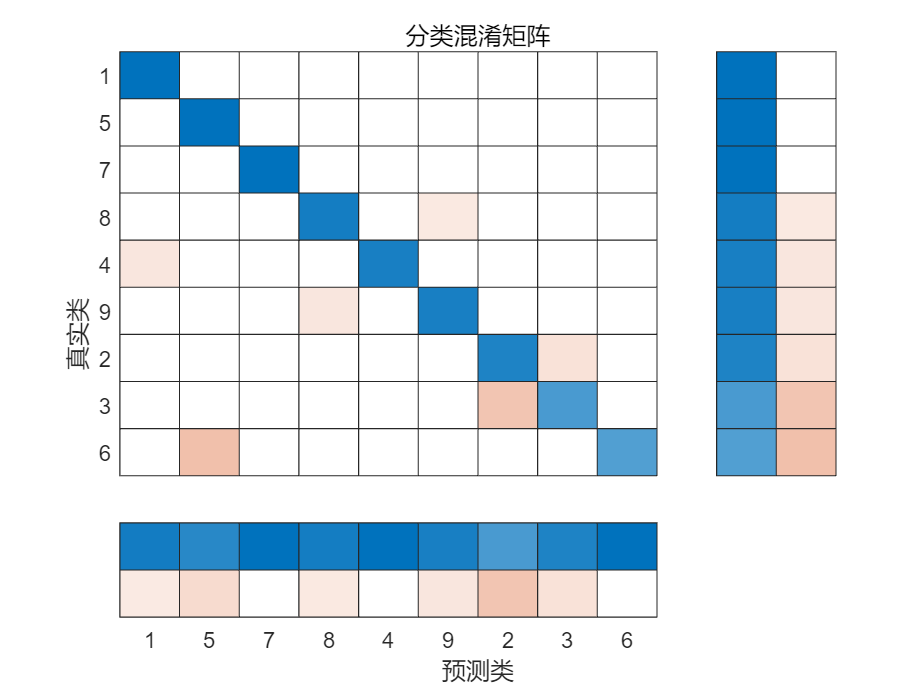

cm = confusionchart(YTrue,YPred);
cm.Title = '分类混淆矩阵';
cm.ColumnSummary = 'column-normalized';
cm.RowSummary = 'row-normalized';
cm.Normalization="row-normalized";
sortClasses(cm,"descending-diagonal");